# 1.

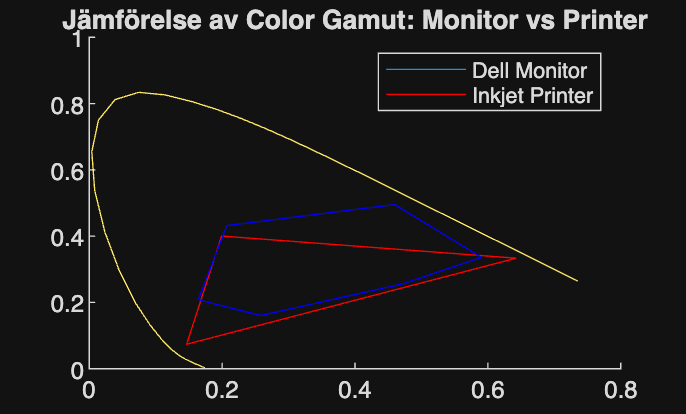

load("Dell.mat")
load("Inkjet.mat")

figure;
hold on;

plot_chrom(im2double(XYZdell), 'r');
plot_chrom(im2double(XYZinkjet), 'b');

legend('Dell Monitor', 'Inkjet Printer');
title('Jämförelse av Color Gamut: Monitor vs Printer');
hold off;

# 2.1

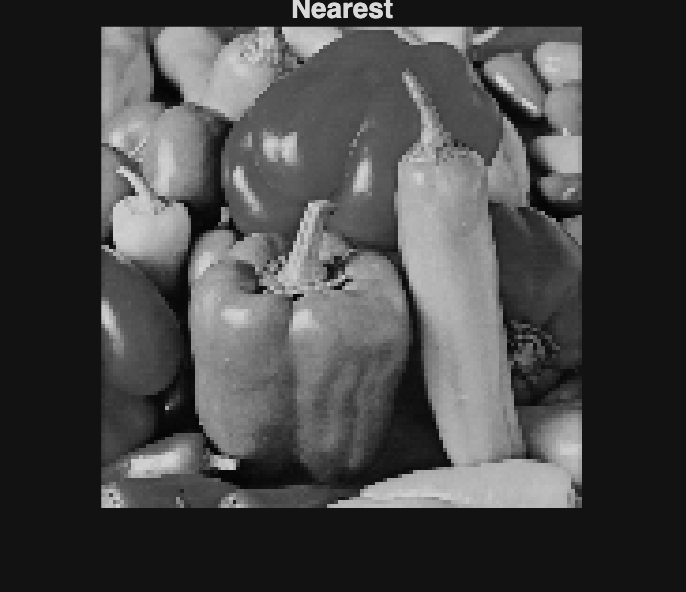

p_double = im2double(imread("peppers_gray.tif"));

p_nearest = imresize(imresize(p_double, 0.25, 'nearest'), 4, 'nearest');

p_bilinear = imresize(imresize(p_double, 0.25, 'bilinear'), 4, 'bilinear');

p_bicubic = imresize(imresize(p_double, 0.25, 'bicubic'), 4, 'bicubic');

imshow(p_nearest)
title("Nearest")

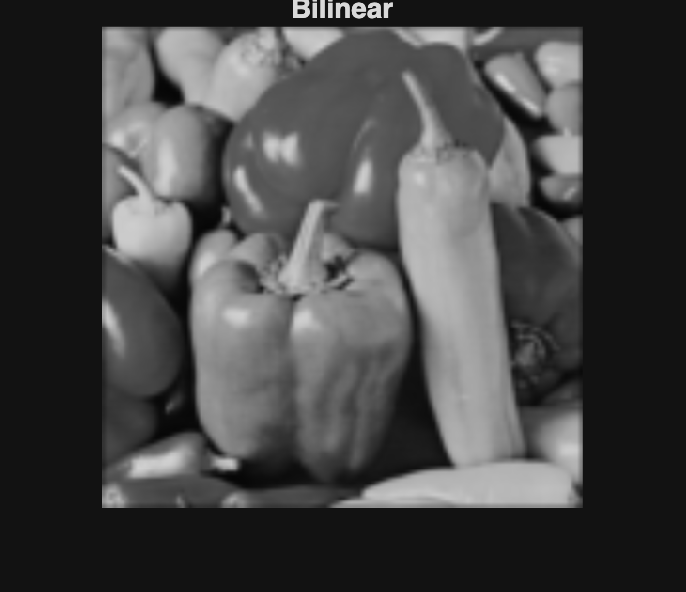


imshow(p_bilinear)
title("Bilinear")

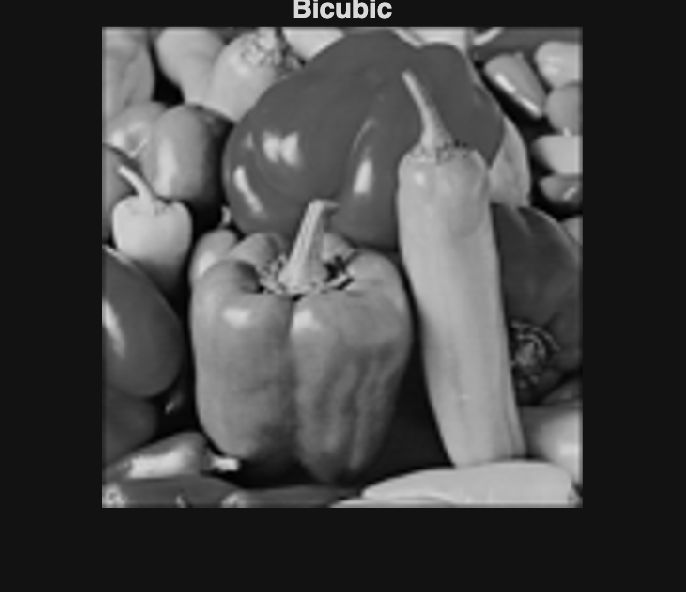


imshow(p_bicubic)
title("Bicubic")


noise_nearest = p_double - p_nearest;
snr_val_nearest = mysnr(p_double, noise_nearest)

snr_val_nearest = 17.0956


noise_bilinear = p_double - p_bilinear;
snr_val_bilinear = mysnr(p_double, noise_bilinear)

snr_val_bilinear = 18.8922


noise_bicubic = p_double - p_bicubic;
snr_val_bicubic = mysnr(p_double, noise_bicubic)

snr_val_bicubic = 19.8538

# 2.2

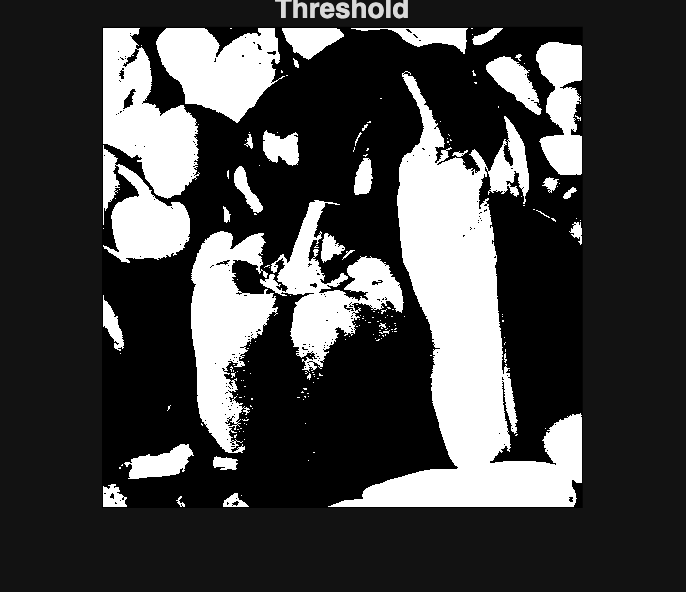

p_threshold = double(p_double >= 0.5);
imshow(p_threshold);
title("Threshold");

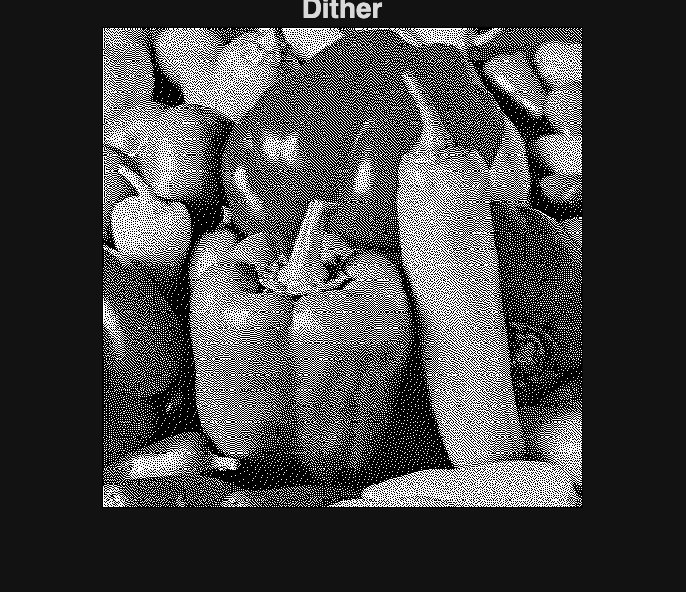


p_halftone = double(dither(p_double));
imshow(p_halftone);
title("Dither");


halftoneSNR = mysnr(p_double , p_halftone - p_double)

halftoneSNR = 0.4112

threshSNR = mysnr(p_double, p_double - p_threshold)

threshSNR = 2.9721

# 3

clc
clear

im = im2double(imread("peppers_gray.tif"));
imThresh = double(im >= 0.5);
imHalftone = double(dither(im));

disp("halftone: " + snr_filter(im,imHalftone - im));

halftone: 13.323


imshow(imHalftone);
title("Dither")


disp("thresh: " + snr_filter(im,imThresh - im));

thresh: 3.3488


imshow(imThresh);
title("Threshold")

# 4

clc
clear
imRGB = im2double(imread("peppers_color.tif"));
imXYZ = rgb2xyz(imRGB);

ppi = 224; d = 10;
sampPerDegree = ppi*d*tan(pi/180);

CIED65_white = [95.05, 100, 108.9];

nearest = imresize(imresize(imRGB,0.25,'nearest'),4,'nearest');
nearest_xyz = rgb2xyz(nearest);
result = mean(scielab(sampPerDegree,imXYZ,nearest_xyz,CIED65_white,'xyz'),"all");

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


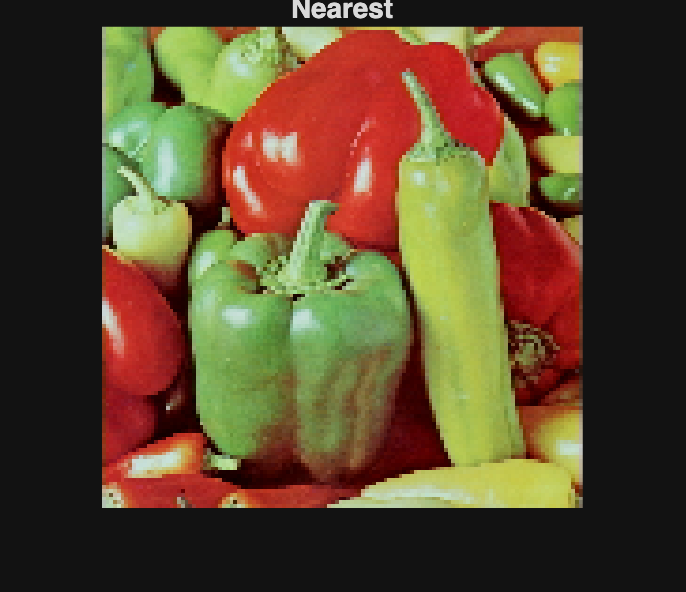

imshow(nearest);
title("Nearest");

disp("nearest: " + result);

nearest: 0.21003



bilinear = imresize(imresize(imRGB,0.25,'bilinear'),4,'bilinear');
bilinear_xyz = rgb2xyz(bilinear);
result = mean(scielab(sampPerDegree,imXYZ,bilinear_xyz,CIED65_white,'xyz'),"all");

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


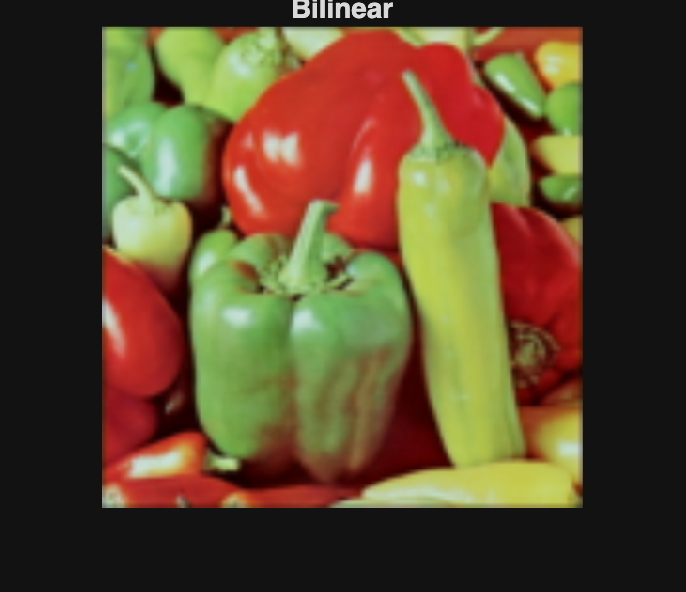

imshow(bilinear);
title("Bilinear");

disp("bilinear: " + result);

bilinear: 0.21919



bicubic = imresize(imresize(imRGB,0.25,'bicubic'),4,'bicubic');
bicubic_xyz = rgb2xyz(bicubic);
result = mean(scielab(sampPerDegree,imXYZ,bicubic_xyz,CIED65_white,'xyz'),"all");

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


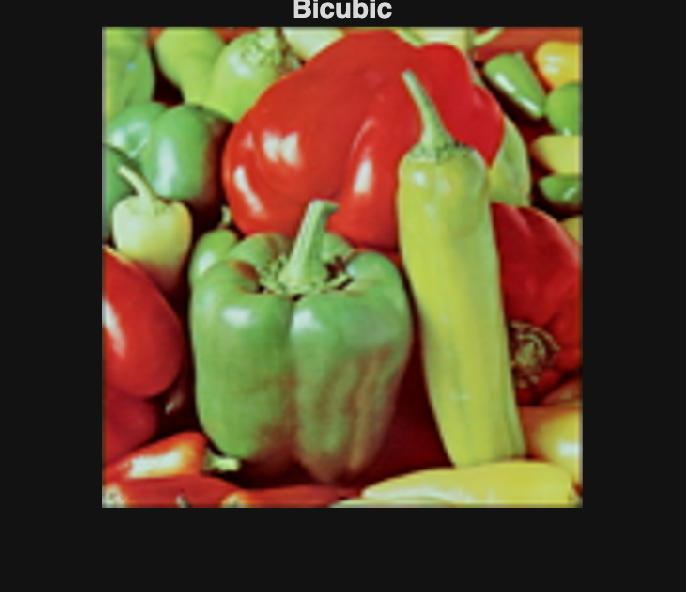

imshow(bicubic);
title("Bicubic");

disp("bicubic: " + result);

bicubic: 0.1481



diff_map_nearest = scielab(sampPerDegree, imXYZ, nearest_xyz, CIED65_white, 'xyz');

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


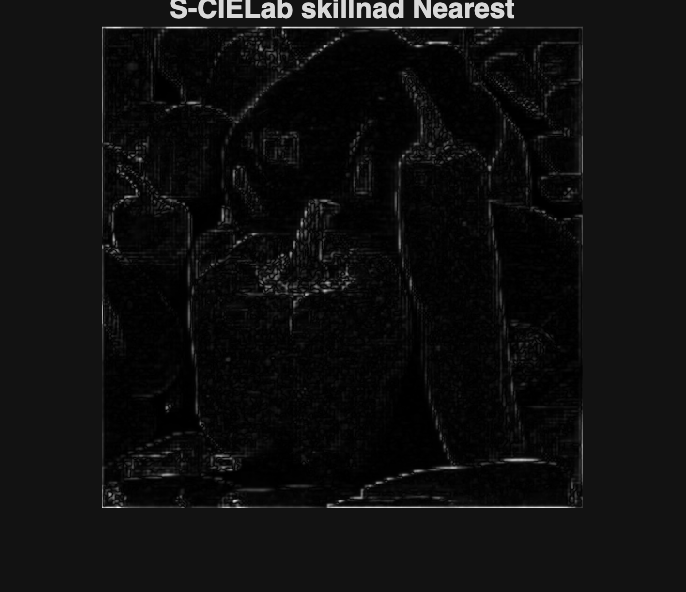

imshow(diff_map_nearest, []);
title('S-CIELab skillnad Nearest');


diff_map_bilinear = scielab(sampPerDegree, imXYZ, bilinear_xyz, CIED65_white, 'xyz');

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


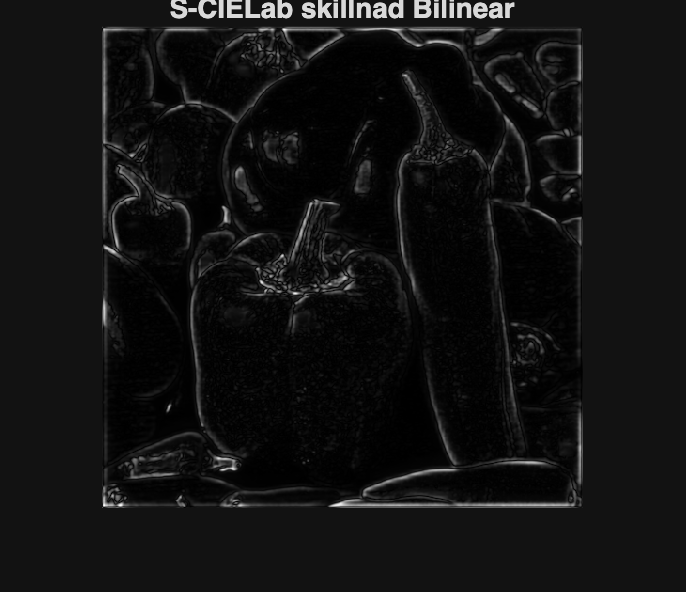

imshow(diff_map_bilinear, []);
title('S-CIELab skillnad Bilinear');


diff_map_bicubic = scielab(sampPerDegree, imXYZ, bicubic_xyz, CIED65_white, 'xyz');

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


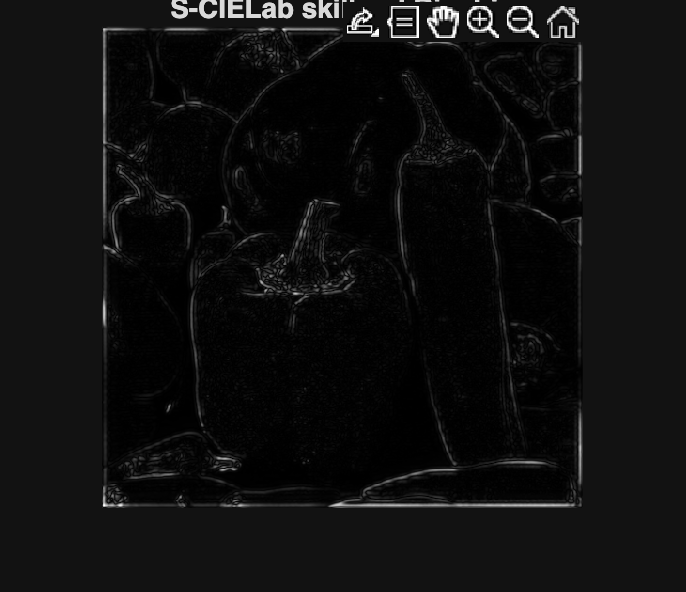

imshow(diff_map_bicubic, []);
title('S-CIELab skillnad Bicubic');